# Evaluación de un robot 

Para determinar si un robot puede realizar una tarea específica es necesario establecer alguna característica relacionada con su funcionamiento 

## Definición la función de manipulabilidad

Función

syms Tij(xij,yij,zij,gij,bij,aij)

Tij(xij,yij,zij,gij,bij,aij) = [cos(aij)*cos(bij) cos(aij)*sin(bij)*sin(gij)-sin(aij)*cos(gij) sin(aij)*sin(gij)+cos(aij)*sin(bij)*cos(gij) xij; sin(aij)*cos(bij) cos(aij)*cos(gij)+sin(aij)*sin(bij)*sin(gij) sin(aij)*sin(bij)*cos(gij)-cos(aij)*sin(gij) yij; -sin(bij) cos(bij)*sin(gij) cos(bij)*cos(gij) zij; 0 0 0 1];


Definición de las tranformaciones

syms T0_1 T1_2 T2_3 T3_P z0_1 theta_1 theta_2 z2_3 theta_3 z3_P

T0_1 = Tij(0,0,z0_1,0,0,theta_1)

$$T0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T1_2 = Tij(0,0,0,0,theta_2,0)

$$T1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T2_3 = Tij(0,0,z2_3,0,theta_3,0)

$$T2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3}\right) & 0 & \cos\left(\theta_{3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3_P = Tij(0,0,z3_P,0,0,0)

$$T3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{3,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T0_P = simplify(T0_1*T1_2*T2_3*T3_P)

$$T0\_P = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & \cos\left(\theta_{2}+\theta_{3}\right) & z_{0,1}+z_{3,P}\,\cos\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,P}\,\sin\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\sin\left(\theta_{2}\right) \end{array}$$

Vector de postura 

syms xi_p

xi_p

$$xi\_p = \xi_{p}$$

xi_p = [T0_P(1,4);T0_P(2,4);T0_P(3,4)]

$$xi\_p = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\sin\left(\theta_{2}\right)\right)\\ \sin\left(\theta_{1}\right)\,\left(z_{3,P}\,\sin\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\sin\left(\theta_{2}\right)\right)\\ z_{0,1}+z_{3,P}\,\cos\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

syms J_theta

J_theta

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_p,[theta_1,theta_2,theta_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{2} & \cos\left(\theta_{1}\right)\,\sigma_{1} & z_{3,P}\,\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2} & \sin\left(\theta_{1}\right)\,\sigma_{1} & z_{3,P}\,\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\sigma_{3}-z_{2,3}\,\sin\left(\theta_{2}\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{3,P}\,\cos\left(\theta_{2}+\theta_{3}\right)+z_{2,3}\,\cos\left(\theta_{2}\right)\\ \sigma_{2}=\sigma_{3}+z_{2,3}\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=z_{3,P}\,\sin\left(\theta_{2}+\theta_{3}\right) \end{array}$$

Cáclulo del índice de manipulabilidad 

syms w_man

w_man

$$w\_man = w_{\mathrm{man}}$$

w_man = simplify(det(J_theta))

$$w\_man = z_{2,3}\,z_{3,P}\,\left(-z_{3,P}\,\cos\left(\theta_{2}\right)\,{\cos\left(\theta_{3}\right)}^{2}+z_{3,P}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\cos\left(\theta_{3}\right)+z_{3,P}\,\cos\left(\theta_{2}\right)+z_{2,3}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)$$

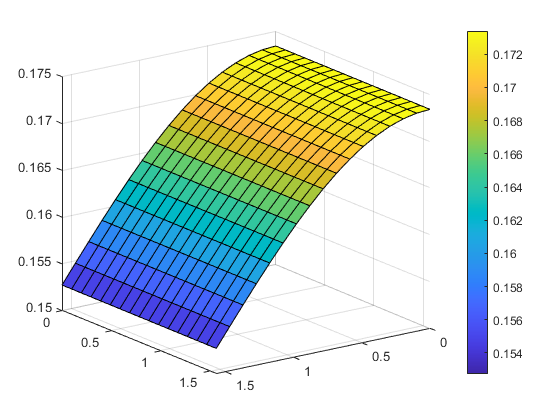


z2_3 = 0.25;
z3_P = 0.2875;

[theta2g,theta3g]= meshgrid(0:pi/32:pi/2,0:pi/32:pi/2);

w_manipulabilidad = z2_3*z3_P*(-z3_P*cos(theta2g)*cos(theta3g)^2+z3_P*sin(theta2g)*sin(theta3g)*cos(theta3g)+z3_P*cos(theta2g)+z2_3*sin(theta2g)*sin(theta3g));

surf(theta2g,theta3g,w_manipulabilidad)
colorbar
view([144.1800 18.4800])



% thet2_r =0:pi/32:pi/2
% thet3_r =0:pi/32:pi/2
% 
% 
% w_rango = zeros(length(thet2_r));
% 
% for i =1:length(thet2_r)
%     
%     for j =1:length(thet3_r)
%     
%     w_rango(i,j) = z2_3*z3_P*(-z3_P*cos(thet2_r(i))*cos(thet3_r(j))^2+z3_P*sin(thet2_r(i))*sin(thet3_r(j))*cos(thet3_r(j))+z3_P*cos(thet2_r(i))+z2_3*sin(thet2_r(i))*sin(thet3_r(j)));
%     
%     end    
% end






s = 10;
H = zeros(s);

for c = 1:s
    for r = 1:s
        H(r,c) = 1/(r+c-1);
    end
end



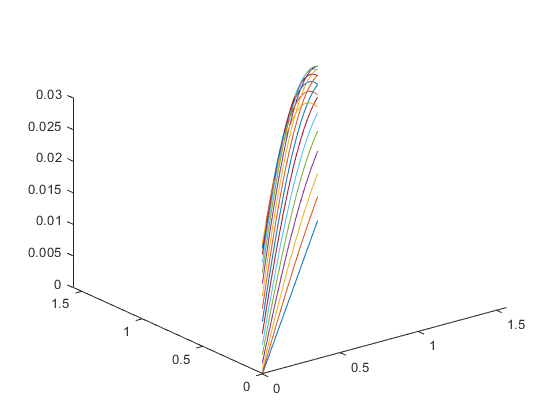



plot3(thet2_r,thet3_r,w_rango)

view([-37.7400 30.0000])